w = 2*pi*10e9; % Define value of w
mu0 = pi*4e-7; % Define value of mu_0
L = 0.1;
Z_L = 100;
n_L = 100;
vp = 1.5*10^8;

Defining $\Gamma$

z = linspace(0, L, n_L)

z =          0    0.0010    0.0020    0.0030    0.0040    0.0051    0.0061    0.0071    0.0081    0.0091    0.0101    0.0111    0.0121    0.0131    0.0141    0.0152    0.0162    0.0172    0.0182    0.0192    0.0202    0.0212    0.0222    0.0232    0.0242    0.0253    0.0263    0.0273    0.0283    0.0293    0.0303    0.0313    0.0323    0.0333    0.0343    0.0354    0.0364    0.0374    0.0384    0.0394    0.0404    0.0414    0.0424    0.0434    0.0444    0.0455    0.0465    0.0475    0.0485    0.0495


Gamma = 0.5 * exp(-100.*z);

Find $a(z)$ and $b(z)$

dGamma = diff(Gamma);
dGamma = cat(2, dGamma(1), dGamma);
a = -2 * dGamma ./ (1 - Gamma.^2);
b = 4j*w*sqrt(mu0)*Gamma ./ (1 - Gamma.^2);

Plot these values

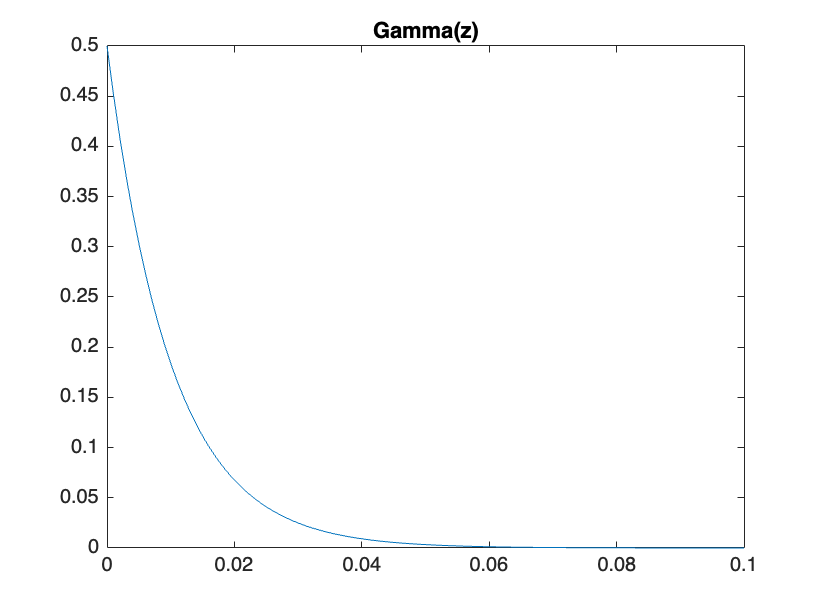

figure
plot(z, Gamma)
title('Gamma(z)')

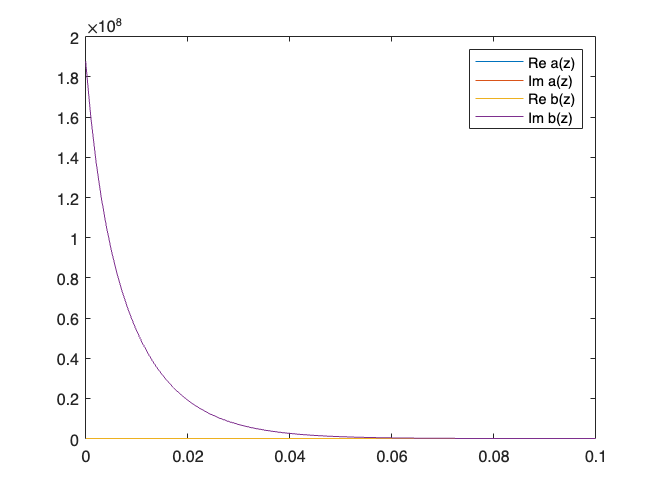

figure
plot(z, real(a))
hold on
plot(z, imag(a))
plot(z, real(b))
plot(z, imag(b))
legend('Re a(z)', 'Im a(z)','Re b(z)', 'Im b(z)')

Define $I(z)$

% Compute A(z) using cumtrapz
A = cumtrapz(z, a);
I = exp(-A+A(n_L))

I =     1.0012    1.0010    1.0009    1.0008    1.0007    1.0007    1.0006    1.0005    1.0005    1.0004    1.0004    1.0004    1.0003    1.0003    1.0003    1.0002    1.0002    1.0002    1.0002    1.0002    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0001    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Now, we find $D(z)=\int_L^zI(x)b(x)dx$

d = times(I, b);
D = cumtrapz(z, d);
D = D-D(n_L);

Plug in the derived formula to get the required plot

xi = ( I./( I(n_L)*(sqrt(mu0)/Z_L) + D ) );
esp = times(xi, xi);
figure
ezplot(z, abs(eps))

Error using ezplot
Input must be a character vector expression, function name, function handle, or INLINE object.